# Clasificación con Separadores Lineales 

**Proyecto I : Programación Cuadrática**

**ITAM**

**Optimización Numérica**

Integrantes:

- Luis Felipe Castro Corrales            181417

- Natalia Hernández Cornejo             xxxxxx

- Dara Ximena Meneses Acosta        xxxxxx

En este proyecto, utilizaremos el método de punto interior para obtener un clasificador lineal. Utilizaremos una base de datos que contiene tres tipos de vinos y que los describe con 13 atributos. El objetivo es, para cada vino, encontrar el hiperplano que maximize el margen entre este y los demás.

clear; close all; clc;

### Importamos los datos de los vinos

En primer lugar, cargamos la base de datos de vinos y los separamos por tipo.

Vt = readmatrix('wine/wine.data','FileType','text');

V1 = Vt(1:59,2:end);
V2 = Vt(60:130,2:end);
V3 = Vt(131:end,2:end);

clear Vt;

% número de atributos de los vinos
n = 13;

#### Separamos el primer vino

Usamos la función *separaLineal* (que se encuentra al final del archivo) para obtener el hiperplano que divide el primer vino de los otros dos. Esta función implementa el programa *qpintpoint2* para resolver el problema cuadrático con restricciones de desigualdad.

AA = V1;
BB = [V2; V3];

[w, beta, ~, ~, ~] = separaLineal(AA,BB);

  1 9003.93409570 
  2 5324.19045178 
  3 2428.50691171 
  4 632.75513501 
  5 306.17517963 
  6 102.20721329 
  7 0.52191083 
  8 0.22490991 
  9 0.03546176 
 10 0.01349456 
 11 0.00663089 
 12 0.00329782 
 13 0.00164424 
 14 0.00082073 
 15 0.00040992 
 16 0.00020481 
 17 0.00010236 
 18 0.00005117 
 19 0.00002558 
 20 0.00001279 
 21 0.00000639 


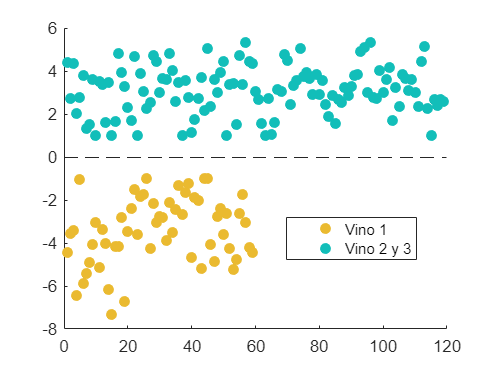


S1 = AA*w + beta;
S2 = BB*w + beta;

figure;
hold on
h = stem(S1,'filled','LineStyle','none','color',[0.9184    0.7308    0.1890]);
hbase = h.BaseLine; 
hbase.LineStyle = '--';
stem(S2,'filled','LineStyle','none','color',[0.0704    0.7457    0.7258])
legend('Vino 1','Vino 2 y 3','Location','best')


%[0.2422    0.1504    0.6603]

#### Separamos el segundo vino

AA = V2;
BB = [V1; V3];

[w, beta, ~, ~, ~] = separaLineal(AA,BB);

  1 43876.82183236 
  2 34223.27773123 
  3 27314.88239790 
  4 24304.53944296 
  5 21946.55665514 
  6 19981.57837055 
  7 16965.15012462 
  8 11676.03447345 
  9 8711.07505496 
 10 6207.33484654 
 11 4966.26440855 
 12 4377.20675984 
 13 4333.70063851 
 14 3793.49119972 
 15 3169.55629695 
 16 2682.81594130 
 17 2158.87340866 
 18 2102.96599139 
 19 1960.83084064 
 20 1695.71216314 
 21 1514.13278123 
 22 1213.71217277 
 23 1135.18487161 
 24 959.83398981 
 25 947.21629621 
 26 944.07971399 
 27 937.86244347 
 28 759.71372572 
 29 757.32784776 
 30 754.35481342 
 31 748.45257425 
 32 672.48773448 
 33 624.18541036 
 34 577.29291977 
 35 577.03498646 
 36 576.98813170 
 37 576.89691831 
 38 576.70470289 
 39 540.57187640 
 40 540.01614841 
 41 539.61442852 
 42 538.81475829 
 43 537.20389118 
 44 530.37755944 
 45 420.55905815 
 46 385.90473227 
 47 381.05323281 
 48 381.02892757 
 49 381.02880603 


 50 381.02880541 


 51 381.02880538 


 52 381.02880533 


 53 316.29108958 
 54 315.74106482 
 55 315.28666692 
 56 314.38553827 
 57 312.59645306 
 58 309.06159244 
 59 302.89728523 
 60 297.49760820 
 61 297.47052917 
 62 297.47002757 
 63 297.46929448 
 64 297.46783330 
 65 297.46491827 
 66 297.45910154 
 67 297.44718467 
 68 297.44676454 
 69 296.33979008 
 70 296.32921503 
 71 296.32775795 
 72 296.04760484 
 73 179.59195198 
 74 170.57191405 
 75 170.52686810 
 76 170.52661773 
 77 170.52656630 
 78 170.52646595 
 79 170.52626576 
 80 170.52586638 
 81 170.52507142 
 82 170.52488614 
 83 170.52488477 
 84 142.78904642 
 85 116.69638041 
 86 116.59860301 
 87 99.82976299 
 88 99.74509611 
 89 99.74274878 
 90 99.73889879 
 91 99.73122267 
 92 99.71591064 
 93 99.68526158 
 94 96.77822987 
 95 96.76370749 
 96 96.76363484 


 97 96.76363440 


 98 96.76363425 


 99 96.76363395 


100 96.76363335 


101 96.76363215 
102 96.76362976 
103 96.76362734 
104 96.76362729 
105 96.76362729 
106 73.84138398 
107 73.72697781 
108 73.72640578 
109 73.72640292 


110 73.72640291 


111 73.72640291 


112 73.72640291 


113 73.72640291 


114 73.72640291 


115 73.72640291 


116 73.72640291 


117 73.72640291 


118 70.67980799 
119 69.97943161 
120 69.49392758 
121 69.49168408 
122 65.75365433 
123 63.39888493 
124 63.38643203 
125 62.51549198 
126 50.39321209 
127 50.33262393 
128 50.33231808 
129 50.33231074 
130 50.33229912 
131 50.33227594 
132 50.33222971 
133 50.33213748 
134 50.33193609 
135 26.22154217 
136 18.28830274 
137 18.25752936 
138 13.00237818 
139 4.21751061 
140 0.09136048 
141 0.00650138 
142 0.00412239 
143 0.00409562 
144 0.00409537 
145 0.00409536 
146 0.00409536 
147 0.00409536 
148 0.00019327 
149 0.00001472 
150 0.00000690 


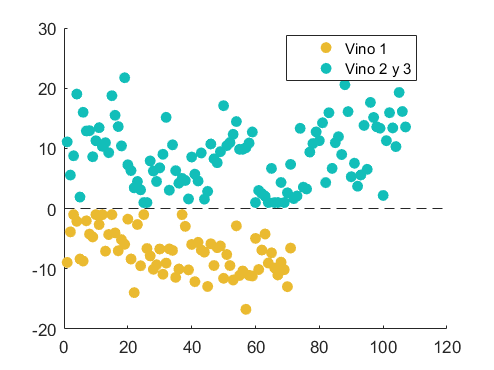


S1 = AA*w + beta;
S2 = BB*w + beta;

figure;
hold on
h = stem(S1,'filled','LineStyle','none','color',[0.9184    0.7308    0.1890]);
hbase = h.BaseLine; 
hbase.LineStyle = '--';
stem(S2,'filled','LineStyle','none','color',[0.0704    0.7457    0.7258])
legend('Vino 1','Vino 2 y 3','Location','best')

#### Separamos el tercer vino

AA = V3;
BB = [V1; V2];

[w, beta, mu, z, iter] = separaLineal(AA,BB);

  1 45398.62788557 
  2 32346.72285503 
  3 26625.43204428 
  4 16304.63511266 
  5 8260.67419911 
  6 6123.44904621 
  7 4991.64820244 
  8 3424.74380663 
  9 2174.08024198 
 10 1041.28539794 
 11 322.66936389 
 12 239.38188022 
 13 217.41891010 
 14 85.42537472 
 15 28.92934330 
 16 15.79900634 
 17 0.60284640 
 18 0.00301468 
 19 0.00002969 
 20 0.00001279 
 21 0.00000639 


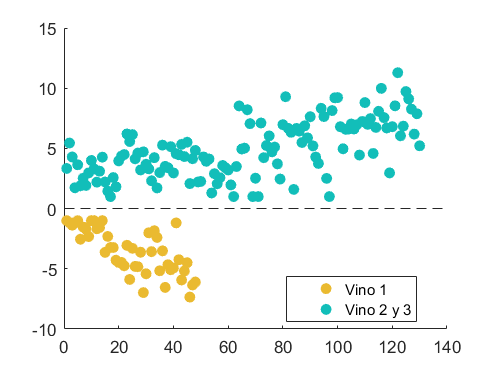


S1 = AA*w + beta;
S2 = BB*w + beta;

figure;
hold on
h = stem(S1,'filled','LineStyle','none','color',[0.9184    0.7308    0.1890]);
hbase = h.BaseLine; 
hbase.LineStyle = '--';
stem(S2,'filled','LineStyle','none','color',[0.0704    0.7457    0.7258])
legend('Vino 1','Vino 2 y 3','Location','best')

### Clasificador lineal para dos conjuntos A y B por el método de punto interior.

Trataremos de encontrar el cero de la función G que describe las condiciones necesarias de primer órden.

function [w, beta, mu, z, iter] = separaLineal(A,B)
    [m, n] = size(A);
    [k, ~] = size(B);

    Q = [  eye(n)    zeros(n,1);
         zeros(1,n)     0
        ];
    c = zeros(n+1,1);

    F = [-A -ones(m,1);
          B  ones(k,1)
        ];
    d = ones(m+k,1);

    % Obtenemos el separador por método del punto interior
    [x, mu, z, iter] = qpintpoint2(Q,F,c,d);
    
    w = x(1:n);
    beta = x(n+1:end);
end